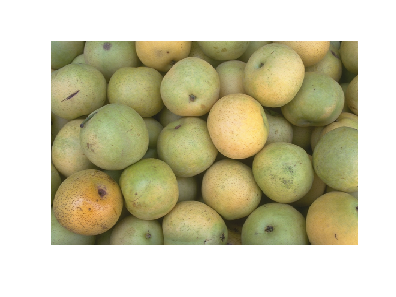

%IA
img = imread("pears.png");


%IB
imshow(img)

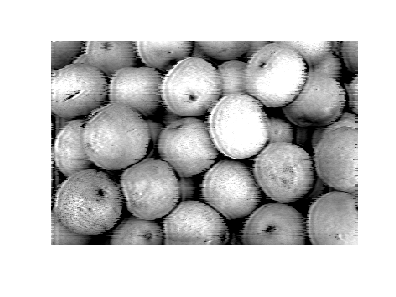



%IC
img = rgb2gray(img);

% https://github.com/291ce4321ac/MIMT
% https://www.mathworks.com/matlabcentral/answers/525517-how-to-create-picture-effects-in-matlab
% This is taken directly from the link above; so for this assignment,
% I am showing the image being turn into B&W effect
retro_strength = [1 0; 0 0; -1 0]*6;
retro_picture = jpegslur(img,retro_strength,1,10,'original');
dpict = picdynamics(img,5,60,'squeeze','rgb');
output = imblend(dpict,retro_picture,1,'contrast',0.9);
output = imblend(mono(meanlines(retro_picture,2),'y'),output,1,'contrast',0.3);


%ID
imshow(output)



%IE
imwrite(output, "img_effect.png")
